**1. 할선법 개요**

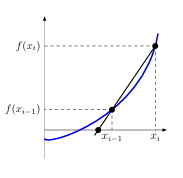

- **할선법**은 Newton-Raphson 방법과 유사하지만, 도함수를 사용하지 않고 두 점을 이용한 기울기로 근을 찾습니다.

- 수식으로 표현하면, 

- Newton-Raphson 방법에 $f'(x)$를 찾기 어려운 경우 

$f^{\prime } \left(x_i \right)\approx \frac{f\left(x_i \right)-f\left(x_{i+1} \right)}{x_i -x_{i+1} }$ 을 $x_{i+1} = x_i - \frac{f(x_i)}{f'(x_i)}$ 에 대입


$$x_{i+1} = x_i - f(x_i) \frac{x_i - x_{i-1}}{f(x_i) - f(x_{i-1})}$$


**2. 할선법의 유도 과정(자세히)**

**2.1. 두 점 사이의 기울기**

- 함수 $f(x)$에 대해 두 점$(x_{i-1}, f(x_{i-1}))$와 $(x_i, f(x_i))$가 주어졌다고 가정합니다.

- 이 두 점을 연결하는 직선의 기울기는 $m = \frac{f(x_i) - f(x_{i-1})}{x_i - x_{i-1}}$�입니다.

**2.2. 기울기를 이용한 직선 방정식**

- 기울기 $m$을 사용하여 점 $(x_i, f(x_i))$을 지나는 직선의 방정식은 $y - f(x_i) = m(x - x_i)$로 나타낼 수 있습니다.

**2.3. 새로운 근의 추정**

- 이 직선이 $ x$축과 교차하는 점, 즉$y = 0$일 때의 $x$값을 찾습니다.

- $y = 0$을 대입하면

$0 - f(x_i) = \frac{f(x_i) - f(x_{i-1})}{x_i - x_{i-1}}(x - x_i)                                     $��


$$x = x_i - f(x_i) \frac{x_i - x_{i-1}}{f(x_i) - f(x_{i-1})}$$


- 입니다.

- 이 새로운 $x$ 값을 $x_{i+1}$�로 두면,


$$x_{i+1} = x_i - f(x_i) \frac{x_i - x_{i-1}}{f(x_i) - f(x_{i-1})}$$


- 이 식이 바로 할선법의 기본 수식입니다.

**3. 수식의 의미와 특징**

- **기울기 근사**: 할선법은 두 점을 연결하는 직선의 기울기를 사용하므로, 함수의 도함수 정보를 직접 요구하지 않습니다.

- **근 추정**: 이 기울기를 사용하여 직선이 x축과 만나는 지점을 새로운 근으로 추정합니다.

- **반복 과정**: 이 과정을 계속 반복하여 근을 점진적으로 찾아갑니다.

**4. 할선법의 수렴 특성**

- 할선법은 **초선형 수렴**을 가집니다.

- 이는 수렴 속도가 $|x_{n+1} - \alpha| \approx C|x_n - \alpha|^p$ 형태로 나타나며,$p \approx 1.618$입니다.

- 여기서 $\alpha$는 실제 근, $C$는 상수, $p$는 수렴 속도를 나타내는 지수입니다.

- **Newton-Raphson 방법**의 수렴 속도인 이차 수렴 $p = 2$보다는 느리지만, 할선법은 도함수를 계산할 필요가 없으므로 효율적입니다.

**5. 수치적 장점과 단점**

- **장점**:

- 도함수가 필요하지 않아 복잡한 함수에도 적용 가능.

- 적절한 초기값 선택 시 빠르게 근에 수렴.

- **단점**:

- 초기값 $x_0$와 $x_1$에 크게 의존하며, 초기값이 좋지 않을 경우 수렴이 느리거나 발산할 수 있음.

- $f(x_i) = f(x_{i-1})$일 경우 분모가 0이 되어 계산이 불가능.

��

**6. 예제 풀이 과정**

- 초기값 $x_0 = 0$, $x_1 = 1$을 사용합니다.

**STEP 1**

- $x_0 = 0$, $f(x_0) = 1$

- $x_1 = 1$,$f(x_1) = -0.63212$

- 새로운$x_2$� 값 계산: $x_2 = 1 - \frac{-0.63212(1 - 0)}{(-0.63212) -1} = 0.61270$

- 상대 오차: $e_t = 8.0\%$

**STEP 2**

- 
$$x_1 = 1, x_2 = 0.61270$$


- 
$$f(x_1) = -0.63212, f(x_2) = -0.07081$$


- 새로운 $x_3$ 값 계산: $x_3 = 0.61270 - \frac{-0.07081(0.61270 - 1)}{-0.07081-(-0.63212)} = 0.56384$

- 상대 오차: $e_t = 0.58\%$

% 할선법과 Newton-Raphson 방법을 비교하는 MATLAB 코드
clear; clc; close all;

% 함수 및 미분 정의
f = @(x) exp(-x) - x;
df = @(x) -exp(-x) - 1;  % Newton-Raphson에서 사용

% 실제 근 (추정치를 통한 정확한 값)
actual_root = fzero(f, 0);

% 초기값 설정
x0_secant = 0;
x1_secant = 1;
x0_newton = 0.5;  % Newton-Raphson 초기값

tolerance = 1e-6;  % 수렴 기준
max_iter = 10;     % 최대 반복 횟수

% 할선법 반복 과정
secant_results = [];
iterations = 0;
error = abs(x1_secant - x0_secant);

while error > tolerance && iterations < max_iter
    x_new = x1_secant - f(x1_secant) * (x1_secant - x0_secant) / (f(x1_secant) - f(x0_secant));
    
    % 상대 오차 및 실제 오차 계산
    ea = abs((x_new - x1_secant) / x_new) * 100;
    et = abs((actual_root - x_new) / actual_root) * 100;
    
    % 결과 저장
    secant_results = [secant_results; iterations+1, x_new, ea, et];
    
    % 값 업데이트
    x0_secant = x1_secant;
    x1_secant = x_new;
    
    error = abs(x1_secant - x0_secant);
    iterations = iterations + 1;
end

% Newton-Raphson 반복 과정
newton_results = [];
iterations = 0;
error = abs(f(x0_newton));

while error > tolerance && iterations < max_iter
    x_new = x0_newton - f(x0_newton) / df(x0_newton);
    
    % 상대 오차 및 실제 오차 계산
    ea = abs((x_new - x0_newton) / x_new) * 100;
    et = abs((actual_root - x_new) / actual_root) * 100;
    
    % 결과 저장
    newton_results = [newton_results; iterations+1, x_new, ea, et];
    
    % 값 업데이트
    x0_newton = x_new;
    error = abs(f(x0_newton));
    iterations = iterations + 1;
end

% 결과를 테이블로 출력
fprintf('Secant Method Results:\n');

Secant Method Results:


fprintf('Iter\tRoot\t\t\tε_a(%%)\t\t\tε_t(%%)\n');

Iter	Root			ε_a(%)			ε_t(%)


for i = 1:size(secant_results, 1)
    fprintf('%d\t%.8f\t%.4e\t%.4e\n', secant_results(i, 1), secant_results(i, 2), secant_results(i, 3), secant_results(i, 4));
end

1	0.61269984	6.3212e+01	8.0326e+00
2	0.56383839	8.6659e+00	5.8273e-01
3	0.56717036	5.8747e-01	4.7727e-03
4	0.56714331	4.7698e-03	2.8556e-06
5	0.56714329	2.8556e-06	1.3977e-11



fprintf('\nNewton-Raphson Method Results:\n');


Newton-Raphson Method Results:


fprintf('Iter\tRoot\t\t\tε_a(%%)\t\t\tε_t(%%)\n');

Iter	Root			ε_a(%)			ε_t(%)


for i = 1:size(newton_results, 1)
    fprintf('%d\t%.8f\t%.4e\t%.4e\n', newton_results(i, 1), newton_results(i, 2), newton_results(i, 3), newton_results(i, 4));
end

1	0.56631100	1.1709e+01	1.4675e-01
2	0.56714317	1.4673e-01	2.2106e-05



% 테이블 형식으로 MATLAB 내에서 결과를 확인
secant_table = array2table(secant_results, 'VariableNames', {'Iteration', 'Root', 'RelativeError(%)', 'TrueError(%)'});
newton_table = array2table(newton_results, 'VariableNames', {'Iteration', 'Root', 'RelativeError(%)', 'TrueError(%)'});

disp('Secant Method Table:');

Secant Method Table:


disp(secant_table);

    Iteration     Root      RelativeError(%)    TrueError(%)
    _________    _______    ________________    ____________

        1         0.6127           63.212            8.0326 
        2        0.56384           8.6659           0.58273 
        3        0.56717          0.58747         0.0047727 
        4        0.56714        0.0047698        2.8556e-06 
        5        0.56714       2.8556e-06        1.3977e-11 




disp('Newton-Raphson Method Table:');

Newton-Raphson Method Table:


disp(newton_table);

    Iteration     Root      RelativeError(%)    TrueError(%)
    _________    _______    ________________    ____________

        1        0.56631         11.709             0.14675 
        2        0.56714        0.14673          2.2106e-05 




% 할선법(Secant Method) 적용 및 시각화
clear; clc; close all;

% 함수 정의
f = @(x) exp(-x) - x;

% 초기값 설정
x0 = 0;
x1 = 1;
tolerance = 1e-6;  % 수렴 기준
max_iter = 100;    % 최대 반복 횟수

% 반복 과정 변수 초기화
iterations = 0;
error = abs(x1 - x0);

% 결과 저장을 위한 배열
x_vals = [x0, x1];
f_vals = [f(x0), f(x1)];

% 할선법 반복 과정
while error > tolerance && iterations < max_iter
    % 새로운 근 계산
    x_new = x1 - f(x1) * (x1 - x0) / (f(x1) - f(x0));
    
    % 값 업데이트
    x0 = x1;
    x1 = x_new;
    x_vals(end + 1) = x1; % 새로운 값 저장
    f_vals(end + 1) = f(x1); % 함수값 저장
    
    % 오차 계산
    error = abs(x1 - x0);
    
    % 반복 횟수 증가
    iterations = iterations + 1;
end

% 결과 출력
fprintf('근은 x = %.6f 입니다.\n', x1);

근은 x = 0.567143 입니다.


fprintf('총 반복 횟수: %d\n', iterations);

총 반복 횟수: 5


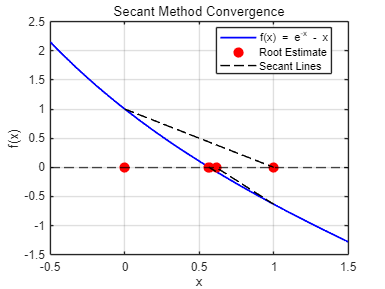


% 시각화
x_range = linspace(-0.5, 1.5, 400); % x 범위 설정
y_range = f(x_range);

figure;
plot(x_range, y_range, 'b-', 'LineWidth', 1.5); % 함수 그래프
hold on;
plot(x_vals, zeros(size(x_vals)), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % 근 추정 점 표시
for i = 2:length(x_vals)
    % 각 반복의 할선을 그리기
    plot([x_vals(i-1), x_vals(i)], [f_vals(i-1), 0], 'k--', 'LineWidth', 1.2);
end
yline(0, '--k'); % x축 그리기

% 그래프 설정
xlabel('x');
ylabel('f(x)');
title('Secant Method Convergence');
legend('f(x) = e^{-x} - x', 'Root Estimate', 'Secant Lines', 'Location', 'best');
grid on;
hold off;

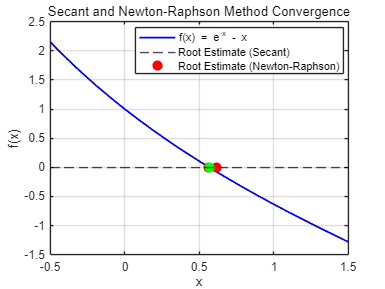

% 할선법과 Newton-Raphson 방법의 동적 그래프 시각화
clear; clc; close all;

% 함수 및 미분 정의
f = @(x) exp(-x) - x;
df = @(x) -exp(-x) - 1;  % Newton-Raphson에서 사용

% 실제 근 (추정치를 통한 정확한 값)
actual_root = fzero(f, 0);

% 초기값 설정
x0_secant = 0;
x1_secant = 1;
x0_newton = 0.5;  % Newton-Raphson 초기값

tolerance = 1e-6;  % 수렴 기준
max_iter = 10;     % 최대 반복 횟수

% x 범위 및 함수 계산
x_range = linspace(-0.5, 1.5, 400);
y_range = f(x_range);

% 동적 그래프 초기 설정
figure;
plot(x_range, y_range, 'b-', 'LineWidth', 1.5); % 함수 그래프
hold on;
yline(0, '--k'); % x축 표시
xlabel('x');
ylabel('f(x)');
title('Secant and Newton-Raphson Method Convergence');
grid on;
legend_labels = {'f(x) = e^{-x} - x', 'Root Estimate (Secant)', 'Root Estimate (Newton-Raphson)'};
secant_plot = plot(NaN, NaN, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % 할선법의 근
newton_plot = plot(NaN, NaN, 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g'); % Newton-Raphson의 근
secant_line = plot(NaN, NaN, 'k--', 'LineWidth', 1.2); % 할선법의 직선
newton_line = plot(NaN, NaN, 'm--', 'LineWidth', 1.2); % Newton-Raphson의 직선

legend(legend_labels, 'Location', 'best');
pause(1);

% 할선법 반복 과정
secant_results = [];
iterations = 0;
error = abs(x1_secant - x0_secant);

while error > tolerance && iterations < max_iter
    x_new_secant = x1_secant - f(x1_secant) * (x1_secant - x0_secant) / (f(x1_secant) - f(x0_secant));
    
    % 그래프 업데이트
    set(secant_plot, 'XData', [get(secant_plot, 'XData') x_new_secant], 'YData', [get(secant_plot, 'YData') 0]);
    set(secant_line, 'XData', [x0_secant, x1_secant], 'YData', [f(x0_secant), 0]);
    pause(1); % 1초 대기
    
    % 값 업데이트
    x0_secant = x1_secant;
    x1_secant = x_new_secant;
    
    % 오차 계산 및 반복 횟수 증가
    error = abs(x1_secant - x0_secant);
    iterations = iterations + 1;
end

% Newton-Raphson 반복 과정
iterations = 0;
error = abs(f(x0_newton));

while error > tolerance && iterations < max_iter
    x_new_newton = x0_newton - f(x0_newton) / df(x0_newton);
    
    % 그래프 업데이트
    set(newton_plot, 'XData', [get(newton_plot, 'XData') x_new_newton], 'YData', [get(newton_plot, 'YData') 0]);
    set(newton_line, 'XData', [x0_newton, x_new_newton], 'YData', [f(x0_newton), 0]);
    pause(1); % 1초 대기
    
    % 값 업데이트
    x0_newton = x_new_newton;
    error = abs(f(x0_newton));
    iterations = iterations + 1;
end

hold off;

function NA8_1_Secant(x_old, x_new)
    func = @(x) exp(-x) - x; % 근을 찾고자 하는 함수 정의
    err_s = 0.5e-4;          % 허용 오차 설정
    iter = 0;                % 반복 횟수 초기화
    

할선법을 사용하여 근을 찾는 중...


    fprintf('Iter\t x_new\t\t f(x_new)\t Relative Error\n'); % 헤더 출력

Iter	 x_new		 f(x_new)	 Relative Error
1	 0.61269984	 -0.07081395	 6.32120559e-01
2	 0.56383839	 0.00518235	 8.66586039e-02
3	 0.56717036	 -0.00004242	 5.87472390e-03
4	 0.56714331	 -0.00000003	 4.76983762e-05
최종 근은 x = 0.56714331, f(x) = -2.53801666e-08 입니다.


    
    while true
        iter = iter + 1;    % 반복 횟수 증가
        f_new = func(x_new); % 새로운 x에서의 함수 값 계산
        f_old = func(x_old); % 이전 x에서의 함수 값 계산
        
        % 할선법 공식 적용
        x_r = x_new - f_new * (x_new - x_old) / (f_new - f_old); 
        
        % 상대 오차 계산
        err_a = abs((x_r - x_new) / x_r); 
        
        % 결과 출력
        fprintf('%d\t %.8f\t %.8f\t %.8e\n', iter, x_r, func(x_r), err_a);
        
        % 값 업데이트
        x_old = x_new; 
        x_new = x_r;
        
        % 수렴 여부 확인
        if (err_a <= err_s), break; end % 허용 오차 이내면 반복 종료
        if iter >= 20, break; end       % 최대 반복 횟수 초과 시 종료
    end
    
    % 최종 결과 출력
    fprintf('최종 근은 x = %.8f, f(x) = %.8e 입니다.\n', x_r, func(x_r));
end


% run_secant.m
% 할선법을 실행하기 위한 스크립트

% 초기값 설정
x0 = 0;     % 첫 번째 초기값
x1 = 1;     % 두 번째 초기값

% 할선법 함수 호출
fprintf('할선법을 사용하여 근을 찾는 중...\n');
NA8_1_Secant(x0, x1); % 정의한 함수 호출

% 수정된 NA8_1_Secant 함수에서 반복 과정과 결과를 출력하도록 설정

**1. 두 방법의 수식**

**선형보간법 (Linear Interpolation)**

- 주어진 두 점 $(x_r, f(x_r))$와 $(x_l, f(x_l))$ 사이에서 $x$값에 해당하는 함수 $f(x)$의 값을 추정합니다.

- 수식은 다음과 같습니다: 

$x_t = x_r - \frac{f(x_r)(x_l - x_r)}{f(x_l) - f(x_r)}$�

- 이 수식은 두 점을 연결하는 직선의 방정식을 사용하여 중간의 값을 추정하는 형태입니다.

**할선법 (Secant Method)**

- 주어진 두 점 $(x_{i-1}, f(x_{i-1}))$와$(x_i, f(x_i))$를 이용하여 새로운 근 $x_{i+1}$�을 찾습니다.

- 수식은 다음과 같습니다:

$x_{i+1} = x_i - \frac{f(x_i)(x_i - x_{i-1})}{f(x_i) - f(x_{i-1})}$�

- 이 수식은 반복적으로 갱신하며, 비선형 방정식$f(x) = 0$의 근을 찾는 데 사용됩니다.

**2. 차이점 설명****목적과 적용**

- **선형보간법**:

- **목적**: 두 점 사이에서 함수 값을 추정하기 위한 방법.

- **적용**: 데이터 분석이나 그래프 작성 시, 주어진 데이터 포인트 사이의 값을 빠르게 추정할 때 사용.

- **할선법**:

- **목적**: 비선형 방정식의 근을 찾기 위한 반복적 수치 해법.

- **적용**: 도함수를 사용하지 않고 근을 찾을 때 주로 사용.

**수렴성**

- **선형보간법**은 근을 찾는 데 사용되지 않으므로 수렴 개념이 없습니다.

- **할선법**은 반복을 통해 점진적으로 근에 접근하며, 수렴 속도가 초선형으로 증가합니다.

**3. 그래프 분석**

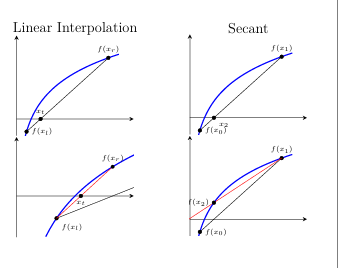

- **선형보간법의 그래프**:

- 그래프에서 $(x_l, f(x_l))$과 $(x_r, f(x_r))$을 연결하는 직선이 보이며, 이 직선을 통해 중간의 $x$값에 해당하는 $f(x)$값을 구합니다.

- 함수가 비선형일 경우 정확도가 떨어질 수 있습니다.

- **할선법의 그래프**:

- 초기 두 점 $(x_{i-1}, f(x_{i-1}))$과 $(x_i, f(x_i))$를 연결하는 직선이 반복적으로 $ x$축과 만나는 지점을 새로운 근으로 사용합니다.

- 반복을 통해 수렴하며, 점점 정확한 근을 찾아가는 과정을 보여줍니다.

**4. 할선법과 선형보간법의 특징 비교**

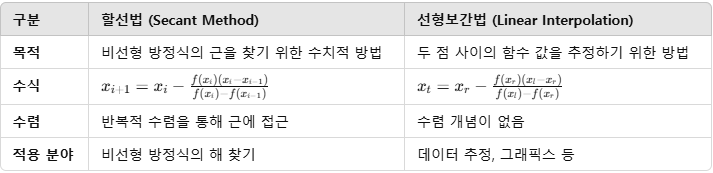

## 유사성

할선법(Secant Method)과 선형보간법(Linear Interpolation Method)은 서로 다른 목적으로 사용되지만, 수학적으로 매우 유사한 과정을 거치기 때문에 서로 거의 동일하다고 간주할 수 있습니다. 특히, 두 방법은 "두 점을 연결하는 직선"을 활용한다는 점에서 핵심적인 유사성이 있습니다.

**1. 두 방법의 기본 개념**

- **할선법**:

- 비선형 방정식$f(x) = 0$의 근을 찾기 위해 사용되며, 반복적인 계산을 통해 정확한 근을 찾아갑니다.

- 두 개의 연속된 점을 연결하는 직선의 기울기를 활용하여 다음 근을 추정합니다.

- **선형보간법**:

- 주어진 두 점 사이의 값을 추정하는 데 사용되며, 두 점을 연결하는 직선의 방정식을 사용하여 새로운 값을 계산합니다.

**2. 수학적으로 동일한 원리**

두 방법은 모두 두 점을 $(x_0, f(x_0))$와 $(x_1, f(x_1))$을 연결하는 직선의 방정식을 사용한다는 점에서 유사합니다.

**할선법의 수식**

- 다음 근을 찾는 할선법의 수식은 다음과 같습니다: 

$x_{i+1} = x_i - \frac{f(x_i)(x_i - x_{i-1})}{f(x_i) - f(x_{i-1})}$�

- 이 식은 두 점 사이의 기울기를 이용하여$f(x) = 0$인 지점을 찾는 과정을 나타냅니다.

**선형보간법의 수식**

- 선형보간법의 수식은 다음과 같습니다:

$x_t = x_r - \frac{f(x_r)(x_l - x_r)}{f(x_l) - f(x_r)}$�

- $f(x)$ 값을 추정할 때 할선법과 동일하게 두 점을 연결하는 직선의 기울기를 활용합니다.

**3. 유사성 분석**

- **기울기 사용**: 두 방법 모두 기울기를 계산하여 직선을 만든다는 점에서 동일합니다.

- **근 추정**:

- 할선법에서는 이 직선이 $x$축과 교차하는 지점을 새로운 근으로 사용합니다.

- 선형보간법에서는 두 점 사이의 특정 위치에서의 값을 추정하는 데 사용합니다.

**4. 동일한 과정의 예시**

만약 $x_0$와 $x_1$이 주어진다면:

- 할선법은$f(x) = 0$을 만족하는 $x$값을 찾으려 하므로, 선형보간법에서$y = 0$을 대입하는 것과 같은 결과를 갖습니다.

- 이는 할선법이 선형보간법의 특별한 경우로 해석될 수 있음을 의미합니다.

**5. 결론: 완벽하게 동일하지 않지만 유사한 알고리즘의 원리를 지니고 있는 접근법**

- 할선법과 선형보간법은 모두 "두 점을 연결하는 직선을 통한 계산"을 기반으로 하며, 수학적으로 동일한 원리를 공유합니다.

- 할선법이 반복적으로 근을 찾아가는 과정에서 어떤 의미에서는 매 단계에서 선형보간법을 사용하고 있다고 볼 수 있습니다.

- 두 방법의 차이는 최종 목적에 있으며, 할선법은 $f(x) = 0$을 찾는 데 집중하는 반면, 선형보간법은 주어진 구간에서의 함수 값을 추정하는 데 집중합니다.

**하지만 결정적인 차이는 선형보간법(Linear Interpolation)은 **$x_l$** 과 **$x_r$**사이에서 해를 찾는 구간법에 속하며, 할선법(Secant)은 **$x_i$**와 **$x_{i+1}$**의 구간을 벗어날 수 있는 계산법인 개구간법에 속하는 것이 가장 큰 계산 구조의 차이점이라고 할 수 있다.**

**또한 위의 예시와 같이 **$\log$**함수 의 경우 할선법을 사용하게 되면 **$x$**의 범위가 음수 범위로 넘어갈 수 있기 때문에 해를 찾지 못하는 경우가 발생하게 된다.**

## 수정된 할선법

**1. 수정된 할선법의 개념**

- 수정된 할선법은 할선법(Secant Method)을 변형하여 근을 찾는 과정에서 수렴 속도를 향상시키는 방법입니다.

- 기존 할선법과 달리 수정된 할선법에서는 도함수 대신 근사 도함수를 사용합니다.

**수정된 할선법의 수식**

- 도함수 근사:

$f'(x_i) \approx \frac{f(x_i + \Delta x_i) - f(x_i)}{\Delta x_i}$�

- 여기서 $\Delta x_i$는 작은 변화량입니다.

- 새로운 근 $x_{i+1}$의 계산식:

$x_{i+1} = x_i - \frac{f(x_i)\Delta x_i}{f(x_i + \Delta x_i) - f(x_i)}$��

**2. 예제 분석주어진 예제**

- 함수: $f(x) = \ln x$

- 초기값: $x_0 = 0.5, x_1 = 5$

**할선법 적용**

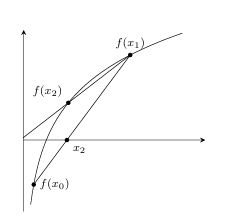

- 첫 번째 반복:

- 
$$x_0 = 0.5, x_1 = 5.0$$


- 새로운 근 $x_2 = 1.8546$

- 두 번째 반복:

- $x_1 = 5.0$, $x_2 = 1.8546$

- 새로운 근 $x_3 = -0.1044$, 수렴하지 않음

**뉴턴-랩슨 방법과의 비교**

- 뉴턴-랩슨 방법을 사용하면 4번의 반복 후 정확한 근$x = 1$에 수렴했습니다.

- 수렴 속도 측면에서 뉴턴-랩슨 방법은 이차 수렴(매우 빠름)인 반면, 수정된 할선법은 그보다 느릴 수 있습니다.

**3. 할선법과 수정된 할선법의 차이점**

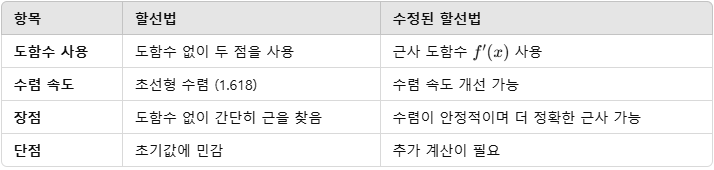

% 수정된 할선법을 사용하여 f(x) = ln(x)의 근을 찾는 MATLAB 코드
clear; clc; close all;

% 함수 정의
f = @(x) log(x);

% 초기값 설정
x0 = 0.5;   % 초기값 1
delta = 1e-4; % 수정된 할선법에서 사용할 작은 변화량
x1 = x0 + delta;   % 초기값 2
tolerance = 1e-6;  % 수렴 기준
max_iter = 20;     % 최대 반복 횟수

% 결과 저장을 위한 변수 초기화
iterations = 0;
error = abs(x1 - x0);

% 결과 저장용 배열 초기화
result_table = [];
x_vals = [x0, x1];
f_vals = [f(x0), f(x1)];

% 그래프 초기 설정
figure;
x_range = linspace(0.1, 6, 400); % x의 범위 설정
y_range = log(x_range);          % y = ln(x)의 그래프
plot(x_range, y_range, 'b-', 'LineWidth', 1.5); % 함수 그래프
hold on;
yline(0, '--k'); % x축 표시
xlabel('x');
ylabel('f(x)');
title('Modified Secant Method Convergence');
grid on;

% 반복 과정
while error > tolerance && iterations < max_iter
    % 현재의 함수값 계산
    f_x1 = f(x1);
    f_x1_delta = f(x1 + delta); % 근사 도함수 계산
    
    % 수정된 할선법 수식 적용
    x_next = x1 - (f_x1 * delta) / (f_x1_delta - f_x1);
    
    % 상대 오차 계산
    if x_next ~= 0
        relative_error = abs((x_next - x1) / x_next) * 100;
    else
        relative_error = NaN;
    end
    
    % 결과 저장
    result_table = [result_table; iterations, x1, f(x1), relative_error];
    
    % 값 업데이트
    x0 = x1;
    x1 = x_next;
    x_vals(end + 1) = x1;
    f_vals(end + 1) = f(x1);
    
    % 오차 계산
    error = abs(x1 - x0);
    
    % 반복 횟수 증가
    iterations = iterations + 1;

최종 근은 x = 1.000000 입니다.


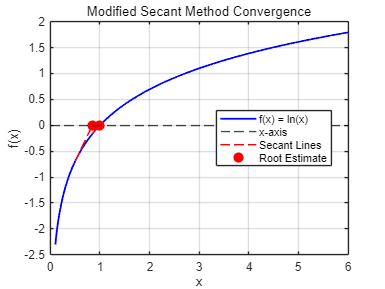

    
    % 시각화 업데이트
    plot(x_vals(end-1:end), [f_vals(end-1), 0], 'r--', 'LineWidth', 1.2); % 수정된 할선 연결선
    plot(x1, 0, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % 새로운 근 추정값 표시

    pause(1); % 1초 대기
end



결과 테이블:


% 최종 결과 출력

Iteration	 x			 f(x)			 Relative Error (%)


fprintf('최종 근은 x = %.6f 입니다.\n', x1);

-------------------------------------------------------------



% 시각화 마무리
hold off;

0		 0.500100	 -6.929472e-01	 40.933830
1		 0.846678	 -1.664354e-01	 14.269440
2		 0.987603	 -1.247454e-02	 1.232146
3		 0.999923	 -7.654220e-05	 0.007654
4		 1.000000	 8.978416e-10	 0.000000


legend('f(x) = ln(x)', 'x-axis', 'Secant Lines', 'Root Estimate', 'Location', 'best');

% 결과를 표로 출력
fprintf('\n결과 테이블:\n');

    Iteration       x          f(x)        RelativeError(%)
    _________    _______    ___________    ________________

        0         0.5001       -0.69295           40.934   
        1        0.84668       -0.16644           14.269   
        2         0.9876      -0.012475           1.2321   
        3        0.99992    -7.6542e-05         0.007654   
        4              1     8.9784e-10       8.9789e-08   



fprintf('Iteration\t x\t\t\t f(x)\t\t\t Relative Error (%%)\n');
fprintf('-------------------------------------------------------------\n');
for i = 1:size(result_table, 1)
    fprintf('%d\t\t %.6f\t %.6e\t %.6f\n', result_table(i, 1), result_table(i, 2), result_table(i, 3), result_table(i, 4));
end

% MATLAB Table 형태로도 출력
result_table = array2table(result_table, 'VariableNames', {'Iteration', 'x', 'f(x)', 'RelativeError(%)'});
disp(result_table);


function NA8_3_Secant(x_new, dx)
    func = @(x) log(x);   % 함수 f(x) = ln(x) 정의
    x_true = 1;           % 정확한 근

    err_s = 5e-4;         % 허용 오차

Iteration	 x_new			 Relative Error (%) 	 True Error (%)


    iter = 0;             % 반복 횟수 초기화

 1    0.88018 & 4.3193e+01 & 1.1982e+01
 2    0.99878 & 1.1875e+01 & 1.2167e-01
 3    1.00006 & 1.2758e-01 & 5.9166e-03
 4    1.00000 & 6.2079e-03 & 2.9130e-04


    max_iter = 50;        % 최대 반복 횟수 설정 (무한 루프 방지)

    while true


다른 Δx = 0.1 값으로 실행:


        iter = iter + 1;   % 반복 횟수 증가
        x_old = x_new;            % 이전 x 값 저장

Iteration	 x_new			 Relative Error (%) 	 True Error (%)


        f_old = func(x_old);      % 이전 함수값     

 1    0.88018 & 4.3193e+01 & 1.1982e+01
 2    0.99878 & 1.1875e+01 & 1.2167e-01
 3    1.00006 & 1.2758e-01 & 5.9166e-03
 4    1.00000 & 6.2079e-03 & 2.9130e-04


        f_new = func(x_new + dx); % 작은 변화량을 더한 새로운 x 값에서의 함수값
        
        % 수정된 할선법 수식
        x_new = x_new - f_old * dx / (f_new - f_old);
        
        % 상대 오차 및 실제 오차 계산
        err_a = abs((x_new - x_old) / (x_new)); % 상대 오차
        err_t = abs((x_new - x_true) / (x_true)); % 실제 오차
        
        % 결과 출력

Iteration	 x_new			 Relative Error (%) 	 True Error (%)


        fprintf("%2d %10.5f & %6.4e & %6.4e\n", iter, x_new, err_a*100, err_t*100);

 1    1.13093 & 5.5789e+01 & 1.3093e+01
 2    0.93671 & 2.0734e+01 & 6.3287e+00
 3    1.02672 & 8.7665e+00 & 2.6720e+00
 4    0.98794 & 3.9249e+00 & 1.2055e+00
 5    1.00529 & 1.7255e+00 & 5.2904e-01
 6    0.99765 & 7.6593e-01 & 2.3510e-01
 7    1.00104 & 3.3864e-01 & 1.0390e-01
 8    0.99954 & 1.5000e-01 & 4.6030e-02
 9    1.00020 & 6.6387e-02 & 2.0370e-02
10    0.99991 & 2.9392e-02 & 9.0192e-03


        
        % 수렴 확인
        if (err_a <= err_s), break; end % 허용 오차 범위 내에 들면 종료


다른 Δx = 1 값으로 실행:


        
        % 최대 반복 횟수 확인

Iteration	 x_new			 Relative Error (%) 	 True Error (%)


        if iter >= max_iter

 1    0.88018 & 4.3193e+01 & 1.1982e+01
 2    0.99878 & 1.1875e+01 & 1.2167e-01
 3    1.00006 & 1.2758e-01 & 5.9166e-03
 4    1.00000 & 6.2079e-03 & 2.9130e-04


            fprintf('최대 반복 횟수 %d에 도달하여 종료합니다.\n', max_iter);
            break;
        end
    end
end


% run_modified_secant.m
% 수정된 할선법을 실행하는 스크립트

% 초기값 설정
initial_x = 0.5; % x_new의 초기값
delta_x = 0.1;     % Δx 값

% 함수 실행
fprintf('Iteration\t x_new\t\t\t Relative Error (%%) \t True Error (%%)\n');
NA8_3_Secant(initial_x, delta_x);

% 다른 Δx 값으로 실행하여 비교
fprintf('\n다른 Δx = 0.1 값으로 실행:\n');
delta_x = 0.1;
fprintf('Iteration\t x_new\t\t\t Relative Error (%%) \t True Error (%%)\n');
NA8_3_Secant(initial_x, delta_x);

% run_modified_secant.m
% 수정된 할선법을 실행하는 스크립트

% 초기값 설정
initial_x = 0.5; % x_new의 초기값
delta_x = 1;     % Δx 값

% 함수 실행
fprintf('Iteration\t x_new\t\t\t Relative Error (%%) \t True Error (%%)\n');
NA8_3_Secant(initial_x, delta_x);

% 다른 Δx 값으로 실행하여 비교
fprintf('\n다른 Δx = 1 값으로 실행:\n');
delta_x = 0.1;
fprintf('Iteration\t x_new\t\t\t Relative Error (%%) \t True Error (%%)\n');
NA8_3_Secant(initial_x, delta_x);

## 핵심요약

- **구간법 : 항상 수렴한다. (초기값 2개 필요) / 이분법, 선형보간법**

- **개구간법 : 빠르다 (초기값 1개 필요) / 고정점 반복법 , N-R , 할선법 **$\Longrightarrow$ **수정된 할선법**